# Section C

## Linear Discriminant Analysis (LDA) 			

We want to see if we can discriminate two deformable and porous objects by touch: the black foam and the car sponge. 			

- Use **LDA **to split the training data in terms of Pressure vs. Vibration, Pressure vs. Temperature and Temperature vs. Vibration. Plot the results, including a line showing the generated LDA function. 							

- Now apply **LDA **to the three-dimensional PVT data. 										

- Comment on the different outcomes. Consider the physical properties of the objects in your answer and how these may have affected the sensor readings. 							

- Repeat the LDA analysis with **your own choice **of two objects. Explain why you have selected those objects for analysis. In other words – what were you trying to test and what did you determine? 							

clc; clear all; close all;
load("F0_PVT.mat")
%load('Sara_data/F0_PVT.mat')

bfoam = zeros(3, 10); 
csponge = zeros(3, 10); 
for i=1:10
    bfoam(1,i) = PVT(i+10:i+19).pressure;
    bfoam(2,i) = PVT(i+10:i+19).vibration;
    bfoam(3,i) = PVT(i+10:i+19).temperature;
    csponge(1,i) = PVT(i+20:i+29).pressure;
    csponge(2,i) = PVT(i+20:i+29).vibration;
    csponge(3,i) = PVT(i+20:i+29).temperature;
end    

% Pressure vs. Vibration,
PV_bf = bfoam(1:2,:);
PV_cs = csponge(1:2,:);

% Pressure vs. Temperature
PT_bf = bfoam([1,3],:);
PT_cs = csponge([1,3],:);

% Temperature vs. Vibration
TV_bf = bfoam([3,2],:);
TV_cs = csponge([3,2],:);

**Pressure vs. Vibration**

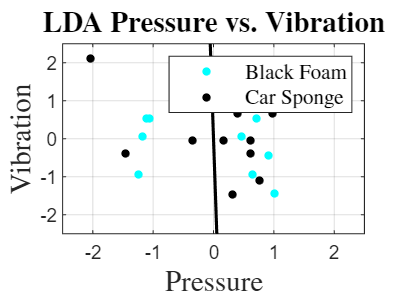

% standardize the data
PV_bf_norm = normalize(PV_bf,2);
PV_cs_norm = normalize(PV_cs,2);

% Get mean
m_bf = mean(PV_bf_norm,2);
m_cs = mean(PV_cs_norm,2);
m = mean([m_bf, m_cs],2);

% scatter matrices
Sw_s = sum(sum((repmat(m_cs,1,10)-PV_cs_norm)*(repmat(m_cs,1,10)-PV_cs_norm)'));
Sw_f = sum(sum((repmat(m_bf,1,10)-PV_bf_norm)*(repmat(m_bf,1,10)-PV_bf_norm)'));
Sw = Sw_s + Sw_f;
Sb = (m_cs-m_bf)*(m_cs-m_bf)';
[vec, ~] = eig(pinv(Sw)*Sb);

% plot(PV_bf(:,1),PV_bf(:,2),'.cyan','MarkerSize',12)
plot(PV_bf_norm(1,:),PV_bf_norm(2,:),'.cyan','MarkerSize',12)
hold on;
plot(PV_cs_norm(1,:),PV_cs_norm(2,:),'.k','MarkerSize',12)
plot([-vec(1,2)*2.5 vec(1,2)*2.5 ],...
[-vec(2,2)*2.5 vec(2,2)*2.5 ],...
'Color','k','lineWidth',1.5)
xlim([-2.5 2.5])
ylim([-2.5 2.5])
xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{LDA Pressure vs. Vibration}','Interpreter', 'Latex', 'Fontsize', 14);
legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10)
grid on;
hold off;

#### Pressure vs. Temperature

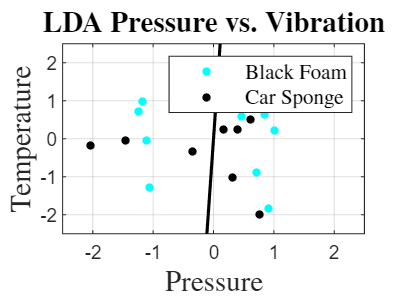

% standardize the data
PT_bf_norm = normalize(PT_bf,2);
PT_cs_norm = normalize(PT_cs,2);

m_bf = mean(PT_bf_norm,2);
m_cs = mean(PT_cs_norm,2);
m = mean([m_bf, m_cs],2);

% scatter matrices
Sw_s = sum(sum((repmat(m_cs,1,10)-PT_cs_norm)*(repmat(m_cs,1,10)-PT_cs_norm)'));
Sw_f = sum(sum((repmat(m_bf,1,10)-PT_bf_norm)*(repmat(m_bf,1,10)-PT_bf_norm)'));
Sw = Sw_s + Sw_f;
Sb = (m_cs-m_bf)*(m_cs-m_bf)';
[vec, val] = eig(pinv(Sw)*Sb);

plot(PT_bf_norm(1,:),PT_bf_norm(2,:),'.cyan','MarkerSize',12)
hold on;
plot(PT_cs_norm(1,:),PT_cs_norm(2,:),'.k','MarkerSize',12)
plot([-vec(1,2)*2.5 vec(1,2)*2.5 ],...
[-vec(2,2)*2.5 vec(2,2)*2.5 ],...
'Color','k','lineWidth',1.5)
xlim([-2.5 2.5])
ylim([-2.5 2.5])
xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{LDA Pressure vs. Vibration}','Interpreter', 'Latex', 'Fontsize', 14);
legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10)
grid on;
hold off;


% %% CHECK 1D Projection:
% % Project data onto line:
% P_bf = PT_bf_norm'*vec(:,2);    % Get 1D projected data
% P_cs = PT_cs_norm'*vec(:,2);    % Get 1D projected data
% plot(P_bf',zeros(1,10),'.','MarkerSize',10)
% hold on;
% plot(P_cs',zeros(1,10),'.','MarkerSize',10)
% grid on;
% hold off;


**Temperature vs. Vibration**

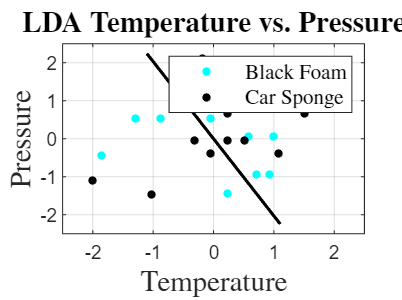

% standardize the data
TV_bf_norm = normalize(TV_bf,2);
TV_cs_norm = normalize(TV_cs,2);

% Get mean
m_bf = mean(TV_bf_norm,2);
m_cs = mean(TV_cs_norm,2);
m = mean([m_bf, m_cs],2);

% scatter matrices
Sw_s = sum(sum((repmat(m_cs,1,10)-TV_cs_norm)*(repmat(m_cs,1,10)-TV_cs_norm)'));
Sw_f = sum(sum((repmat(m_bf,1,10)-TV_bf_norm)*(repmat(m_bf,1,10)-TV_bf_norm)'));
Sw = Sw_s + Sw_f;
Sb = (m_cs-m_bf)*(m_cs-m_bf)';
[vec, ~] = eig(pinv(Sw)*Sb);

% plot(TV_bf_norm(1,:),TV_bf_norm(2,:),'.red','MarkerSize',12)
plot(TV_bf_norm(1,:),TV_bf_norm(2,:),'.cyan','MarkerSize',12)
hold on;
plot(TV_cs_norm(1,:),TV_cs_norm(2,:),'.k','MarkerSize',12)
plot([-vec(1,2)*2.5 vec(1,2)*2.5 ],...
[-vec(2,2)*2.5 vec(2,2)*2.5 ],...
'Color','k','lineWidth',1.5)
xlim([-2.5 2.5])
ylim([-2.5 2.5])
xlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{LDA Temperature vs. Pressure}','Interpreter', 'Latex', 'Fontsize', 14);
legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10)
grid on;
hold off;

b. Now apply **LDA **to the three-dimensional PVT data. 								

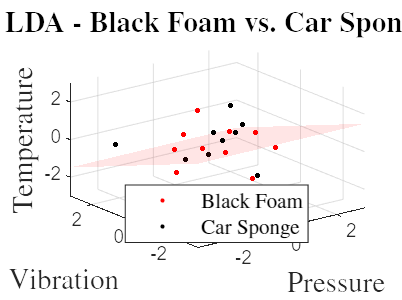

% standardize the data
bf_norm = normalize(bfoam,2);
cs_norm = normalize(csponge,2);

% Get mean
m_bf = mean(bf_norm,2);
m_cs = mean(cs_norm,2);
m = mean([m_bf, m_cs],2);

% scatter matrices
Sw_s = sum(sum((repmat(m_cs,1,10)-cs_norm)*(repmat(m_cs,1,10)-cs_norm)'));
Sw_f = sum(sum((repmat(m_bf,1,10)-bf_norm)*(repmat(m_bf,1,10)-bf_norm)'));
Sw = Sw_s + Sw_f;
Sb = (m_cs-m_bf)*(m_cs-m_bf)';
[vec, val] = eig(pinv(Sw)*Sb);

scatter3(bf_norm(1,:),bf_norm(2,:),bf_norm(3,:),'.red','SizeData',60)
hold on;
scatter3(cs_norm(1,:),cs_norm(2,:),cs_norm(3,:),'.k','SizeData',60)
x = [-vec(1,3) -vec(1,2) vec(1,3) vec(1,2)]*20;
y = [-vec(2,3) -vec(2,2) vec(2,3) vec(2,2)]*20;
z = [-vec(3,3) -vec(3,2) vec(3,3) vec(3,2)]*20;
patch(x,y,z,'red','facealpha',0.1)
xlim([-3 3])
ylim([-3 3])
zlim([-3 3])
xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{LDA - Black Foam vs. Car Sponge}','Interpreter', 'Latex', 'Fontsize', 14);
legend(['Black Foam';'Car Sponge'],'Interpreter', 'Latex', 'Fontsize', 10,'Location', 'best')
grid on;
hold off;	

c. Repeat the LDA analysis with **your own choice **of two objects. Explain why you have selected those objects for analysis. In other words – what were you trying to test and what did you determine? 							

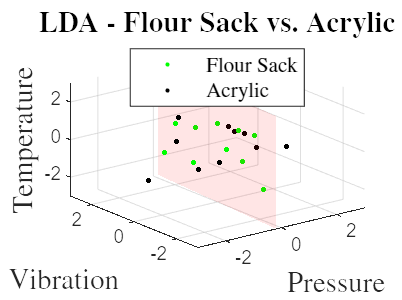

% Try Flour Sack and Acrylic

fsack = zeros(3, 10); 
acrylic = zeros(3, 10);
for i=1:10
    fsac(1,i) = PVT(i+30:i+39).pressure;
    fsac(2,i) = PVT(i+30:i+39).vibration;
    fsac(3,i) = PVT(i+30:i+39).temperature;
    acrylic(1,i) = PVT(i:i+9).pressure;
    acrylic(2,i) = PVT(i:i+9).vibration;
    acrylic(3,i) = PVT(i:i+9).temperature;
end   

% standardize the data
fsack_norm = normalize(fsac,2);
acrylic_norm = normalize(acrylic,2);

% Get mean
m_fs = mean(fsack_norm,2);
m_a = mean(acrylic_norm,2);
m = mean([m_fs, m_a],2);

% scatter matrices
Sw_s = sum(sum((repmat(m_fs,1,10)-fsack_norm)*(repmat(m_fs,1,10)-fsack_norm)'));
Sw_f = sum(sum((repmat(m_a,1,10)-acrylic_norm)*(repmat(m_a,1,10)-acrylic_norm)'));
Sw = Sw_s + Sw_f;
Sb = (m_fs-m_a)*(m_fs-m_a)';
[vec, val] = eig(pinv(Sw)*Sb);

scatter3(fsack_norm(1,:),fsack_norm(2,:),fsack_norm(3,:),'.green','SizeData',60)
hold on;
scatter3(acrylic_norm(1,:),acrylic_norm(2,:),acrylic_norm(3,:),'.k','SizeData',60)
x = [-vec(1,3) -vec(1,2) vec(1,3) vec(1,2)]*20;
y = [-vec(2,3) -vec(2,2) vec(2,3) vec(2,2)]*20;
z = [-vec(3,3) -vec(3,2) vec(3,3) vec(3,2)]*20;
patch(x,y,z,'red','facealpha',0.1)
xlim([-3 3])
ylim([-3 3])
zlim([-3 3])
xlabel('Pressure','Interpreter', 'Latex', 'Fontsize', 14)
ylabel('Vibration','Interpreter', 'Latex', 'Fontsize', 14)
zlabel('Temperature','Interpreter', 'Latex', 'Fontsize', 14)
title('\textbf{LDA - Flour Sack vs. Acrylic}','Interpreter', 'Latex', 'Fontsize', 14);
legend('Flour Sack','Acrylic','Interpreter', 'Latex', 'Fontsize', 10,'Location', 'best')
grid on;
hold off;	